# **ZOMATO's EXPLORATORY DATA ANALYSIS**

## **Importing the Dataset**

dataframe = importZomatoData("zomato.csv")

dataframe = 9551×21 table
    RestaurantID                  RestaurantName                  CountryCode          City                                                 Address                                                              Locality                                              LocalityVerbose                           Longitude    Latitude                  Cuisines                  AverageCostForTwo        Currency        HasTableBooking    HasOnlineDelivery    IsDeliveringNow    SwitchToOrderMenu    PriceRange    AggregateRating    RatingColor    RatingText    Votes
    ____________    _____________

## Converting into Categorical Arrays

dataframe.RestaurantName = categorical(dataframe.RestaurantName);
dataframe.Cuisines = categorical(dataframe.Cuisines);
dataframe

dataframe = 9551×21 table
    RestaurantID                 RestaurantName                 CountryCode          City                                                 Address                                                              Locality                                              LocalityVerbose                           Longitude    Latitude                 Cuisines                 AverageCostForTwo        Currency        HasTableBooking    HasOnlineDelivery    IsDeliveringNow    SwitchToOrderMenu    PriceRange    AggregateRating    RatingColor    RatingText    Votes
    ____________    _________________

## City with the Highest Number of Orders

City_high_num_Order = groupcounts(dataframe, "City");
City_high_num_Order = sortrows(City_high_num_Order,'GroupCount','descend')

City_high_num_Order = 141×3 table
        City        GroupCount    Percent
    ____________    __________    _______

    New Delhi          5473        57.303
    Gurgaon            1118        11.706
    Noida              1080        11.308
    Faridabad           251         2.628
    Ghaziabad            25       0.26175
    Ahmedabad            21       0.21987
    Amritsar             21       0.21987
    Bhubaneshwar         21       0.21987
    Guwahati             21       0.21987
    Lucknow              21       0.21987
    Abu Dhabi            20        0.2094
    Agra                 20        0.2094
    Albany               20        0.2094
    Allahabad            20        0.2094
    Ankara               20        0.2094
    Athens               20        0.2094


dataframe_NewDelhi = dataframe(dataframe.City == 'New Delhi',:)

dataframe_NewDelhi = 5473×21 table
    RestaurantID       RestaurantName       CountryCode      City                                           Address                                                  Locality                           LocalityVerbose                 Longitude    Latitude                        Cuisines                        AverageCostForTwo         Currency         HasTableBooking    HasOnlineDelivery    IsDeliveringNow    SwitchToOrderMenu    PriceRange    AggregateRating    RatingColor    RatingText    Votes
    ____________    ____________________    ___________  

According to the data, we can say that, ***NEW DELHI ***is the city with the highest number of orders (***roughly around 57.3029%***)

## Most Ordered Cuisines from the city with highest number of orders

Most_Ordered_Cuisines = groupcounts(dataframe_NewDelhi, "Cuisines");
Most_Ordered_Cuisines = sortrows(Most_Ordered_Cuisines,'GroupCount','descend')

Most_Ordered_Cuisines = 892×3 table
               Cuisines               GroupCount    Percent
    ______________________________    __________    _______

    North Indian                         658        12.023 
    North Indian, Chinese                284        5.1891 
    Fast Food                            242        4.4217 
    Chinese                              228        4.1659 
    North Indian, Mughlai                207        3.7822 
    Cafe                                 158        2.8869 
    Street Food                          123        2.2474 
    Bakery                               122        2.2291 
    North Indian, Mughlai, Chinese       120        2.1926 
    Bakery, Desserts                     117        2.1378 
    Chinese, Fast Food                    99        1.8089 
    Pizza, Fast Food                      92         1.681 
    Mithai, Street Fo

Top 3 most ordered cuisines from ***New Delhi*** are: -

- North Indian (approx. 12.02%)

- A combination of North Indian and Chinese (approx 5.18%)

- Fast Food (approx. 4.42)

## Highest Rated Locality

Highest_Rated_Locality = groupcounts(dataframe_NewDelhi, ["Locality", "Cuisines" "AggregateRating", "Votes"]);
Highest_Rated_Locality = sortrows(Highest_Rated_Locality, ['AggregateRating'],['descend'])

Highest_Rated_Locality = 5189×6 table
             Locality                                     Cuisines                           AggregateRating    Votes    GroupCount    Percent 
    ___________________________    ______________________________________________________    _______________    _____    __________    ________

    Connaught Place                Ice Cream                                                       4.9          2620         1         0.018272
    Friends Colony                 Modern Indian                                                   4.9          1934         1         0.018272
    Janpath                        Modern Indian                                                   4.9           408         1         0.018272
    Rajouri Garden                 No

***Connaught Place*** has the highest Aggregate Rating of 4.9

## Highest Votes Locality

Highest_Votes_Locality = sortrows(Highest_Rated_Locality,'Votes','descend')

Highest_Votes_Locality = 5189×6 table
             Locality                                    Cuisines                            AggregateRating    Votes    GroupCount    Percent 
    __________________________    _______________________________________________________    _______________    _____    __________    ________

    Hauz Khas Village             Continental, American, Asian, North Indian                       4.3          7931         1         0.018272
    Connaught Place               South Indian                                                     4.3          5172         1         0.018272
    Khan Market                   Italian, Continental, European, Cafe                             4.5          4986         1         0.018272
    Connaught Place               Ame

***Hauz Khas Village*** has the highest number of *votes* approx *7931* with an Aggregate Rating of 4.3

## Most Rated Text

Most_Rated_Text = groupcounts(dataframe_NewDelhi, "RatingText");
Most_Rated_Text = Most_Rated_Text(~ismissing(Most_Rated_Text.Percent),:);
Most_Rated_Text = sortrows(Most_Rated_Text,'Percent','descend')

Most_Rated_Text = 6×3 table
    RatingText    GroupCount    Percent
    __________    __________    _______

    Average          2495       45.587 
    Not rated        1425       26.037 
    Good             1128        20.61 
    Very Good         300       5.4815 
    Poor               97       1.7723 
    Excellent          28       0.5116 


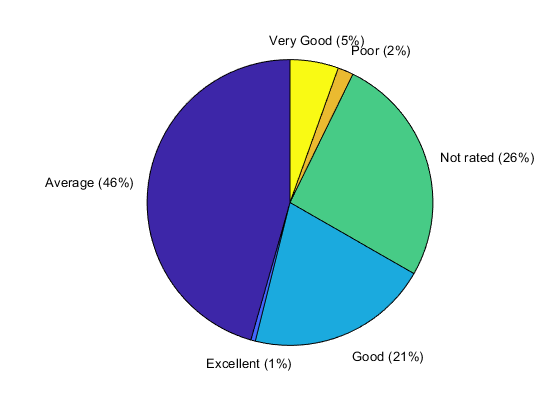

pie(dataframe_NewDelhi.RatingText)

***"AVERAGE" *** is the most rated text in **New Delhi**